## MathTool HW6

## 2024-12-11

### Question 1 Fitting a 2AFC psychometric function

## Part a)

% function nll = nloglik(mu, sigma, lambda, I, T, B)
%     %mu: mean
%     %sigma: standard deviation
%     %lambda: lapse rate
%     %I: stimulus intensities
%     %T: trials per intensity
%     %B: num of correct response
% 
%     p_correct = lambda / 2 + (1 - lambda) * normcdf(I, mu, sigma);
%     p_correct = max(min(p_correct, 1 - 1e-6), 1e-6);
%     likelihoods = B .* log(p_correct) + (T - B) .* log(1 - p_correct);
%     nll = -np.sum(likelihoods);
% end 

## Part b)

T = ones(1, 7) * 100;     %trials per intensity
I = 1:7; %stimulus intensities
lambda_true = 0.05; %lapse rate
mu_true = 4; %mean
sigma_true = 1; %standard deviation

%p correct in this case
p_correct_b = lambda_true / 2 + (1 - lambda_true) * normcdf(I, mu_true, sigma_true);

%B: num of correct response
B = binornd(T, p_correct_b);

nll_nloglik = @(x) nloglik(x(1), x(2), x(3), I, T, B);
start_point = [2, 2, 0.05];

[params, nll] = fminsearch(nll_nloglik, start_point);

disp('Estimated parameters:');

Estimated parameters:


disp(['mu: ', num2str(params(1))]);

mu: 3.9492


disp(['sigma: ', num2str(params(2))]);

sigma: 1.0787


disp(['lambda: ', num2str(params(3))]);

lambda: 0.024181



disp('True parameters:');

True parameters:


disp(['mu: ', num2str(mu_true)]);

mu: 4


disp(['sigma: ', num2str(sigma_true)]);

sigma: 1


disp(['lambda: ', num2str(lambda_true)]);

lambda: 0.05


For mean and standard deviation, the estimations were close to the true value. However, the lapse rate is not very close.

## Part c)

%from part b
p_correct_c = lambda_true / 2 + (1 - lambda_true) * normcdf(I, mu_true, sigma_true);
B = binornd(T, p_correct_c);
nll_nloglik = @(x) nloglik(x(1), x(2), x(3), I, T, B);
start_point = [2, 2, 0.05];

%optimizations
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton', 'Display', 'iter');
[params, nll, exitflag, output, grad, hessian] = fminunc(nll_nloglik, start_point, options);

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4          404.309                           154
     1          12          378.015     0.00190608           81.2  
     2          24          307.069        6.91627            114  
     3          32          293.198            0.1            361  
     4          44          274.375      0.0331341            289  
     5          48          272.266              1           80.8  
     6          52          266.578              1           56.6  
     7          56          263.198              1            148  
     8          60          260.698              1             44  
     9          64          259.233              1           17.6  
    10          68          258.872              1           4.51  
    11          72          258.783              1           6.38  
    12          80          250.368              

mu_est = params(1);
sigma_est = params(2);
lambda_est = params(3);

%covariance matrix as the inverse of the hessian matrix
cov_matrix = inv(hessian);

%compute sd
std_mu = sqrt(cov_matrix(1, 1));
std_sigma = sqrt(cov_matrix(2, 2));
std_lambda = sqrt(cov_matrix(3, 3));

%95% CI
CI_mu = [mu_est - 1.96 * std_mu, mu_est + 1.96 * std_mu];
CI_sigma = [sigma_est - 1.96 * std_sigma, sigma_est + 1.96 * std_sigma];
CI_lambda = [lambda_est - 1.96 * std_lambda, lambda_est + 1.96 * std_lambda];

fprintf('Estimated parameters:\n');

Estimated parameters:


fprintf('mu: %.4f, 95%% CI: [%.4f, %.4f]\n', mu_est, CI_mu(1), CI_mu(2));

mu: 4.0799, 95% CI: [3.9096, 4.2501]


fprintf('sigma: %.4f, 95%% CI: [%.4f, %.4f]\n', sigma_est, CI_sigma(1), CI_sigma(2));

sigma: 1.0931, 95% CI: [0.8699, 1.3162]


fprintf('lambda: %.4f, 95%% CI: [%.4f, %.4f]\n', lambda_est, CI_lambda(1), CI_lambda(2));

lambda: 0.0482, 95% CI: [0.0033, 0.0930]



fprintf('\nTrue parameters:\n');


True parameters:


fprintf('mu: %.4f, sigma: %.4f, lambda: %.4f\n', mu_true, sigma_true, lambda_true);

mu: 4.0000, sigma: 1.0000, lambda: 0.0500


%Checking whether true parameters fall in the confidence interval
in_CI_mu = (mu_true >= CI_mu(1) && mu_true <= CI_mu(2));
in_CI_sigma = (sigma_true >= CI_sigma(1) && sigma_true <= CI_sigma(2));
in_CI_lambda = (lambda_true >= CI_lambda(1) && lambda_true <= CI_lambda(2));
fprintf('\nDo the true parameters fall within the confidence intervals?\n');


Do the true parameters fall within the confidence intervals?


fprintf('mu: %d, sigma: %d, lambda: %d\n', in_CI_mu, in_CI_sigma, in_CI_lambda);

mu: 1, sigma: 1, lambda: 1


Thus, mu and sigma fall with in the confidence internal but not the lamda.

Which is similar to what we observed in part b),where the lapse rate is not close to true parameter.

## Part d)

nBootstrap = 500;
paramsBootstrap = zeros(nBootstrap,3);

for i = 1:nBootstrap
    B_resampled = arrayfun(@(b, t) binornd(t, b ./ t, [1, 1]), B, T);
    nll_resampled = @(x) nloglik(x(1), x(2), x(3), I, T, B_resampled);
    paramsResampled = fminsearch(nll_resampled, start_point);
    paramsBootstrap(i, :) = paramsResampled;
end 

bootstrap_mu = paramsBootstrap(:, 1);
bootstrap_sigma = paramsBootstrap(:, 2);
bootstrap_lambda = paramsBootstrap(:, 3);

CI_mu_bootstrap = prctile(bootstrap_mu, [2.5, 97.5]);
CI_sigma_bootstrap = prctile(bootstrap_sigma, [2.5, 97.5]);
CI_lambda_bootstrap = prctile(bootstrap_lambda, [2.5, 97.5]);

fprintf('Bootstrap confidence intervals:\n');

Bootstrap confidence intervals:


fprintf('mu: [%.4f, %.4f]\n', CI_mu_bootstrap(1), CI_mu_bootstrap(2));

mu: [3.8989, 4.2536]


fprintf('sigma: [%.4f, %.4f]\n', CI_sigma_bootstrap(1), CI_sigma_bootstrap(2));

sigma: [0.8788, 1.3227]


fprintf('lambda: [%.4f, %.4f]\n', CI_lambda_bootstrap(1), CI_lambda_bootstrap(2));

lambda: [0.0043, 0.0922]


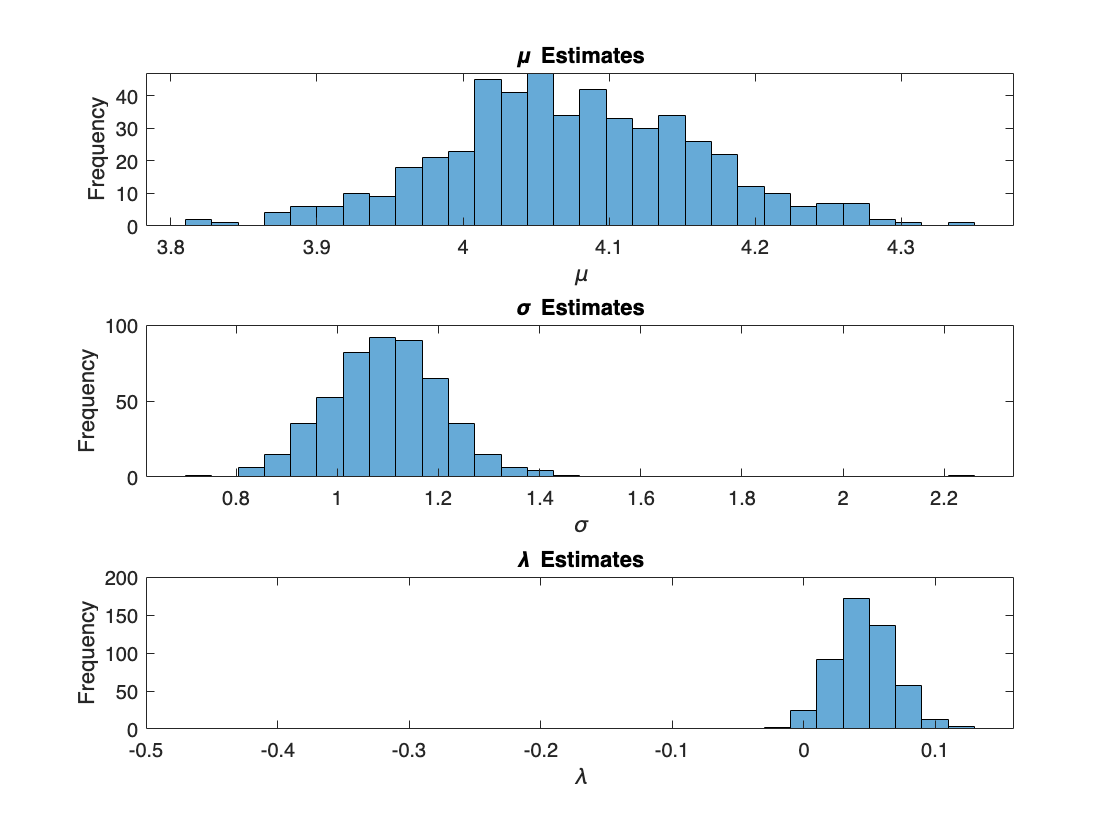

figure;
subplot(3, 1, 1);
histogram(bootstrap_mu, 30);
title('\mu Estimates');
xlabel('\mu');
ylabel('Frequency');

subplot(3, 1, 2);
histogram(bootstrap_sigma, 30);
title('\sigma Estimates');
xlabel('\sigma');
ylabel('Frequency');

subplot(3, 1, 3);
histogram(bootstrap_lambda, 30);
title('\lambda Estimates');
xlabel('\lambda');
ylabel('Frequency');

%To compare with precious part:
%Comparison between confidence intervals

fprintf('\nComparison of confidence intervals:\n');


Comparison of confidence intervals:


fprintf('mu:\n');

mu:


fprintf('  Hessian-based CI: [%.4f, %.4f]\n', CI_mu(1), CI_mu(2));

  Hessian-based CI: [3.9096, 4.2501]


fprintf('  Bootstrap CI:     [%.4f, %.4f]\n', CI_mu_bootstrap(1), CI_mu_bootstrap(2));

  Bootstrap CI:     [3.8989, 4.2536]


fprintf('sigma:\n');

sigma:


fprintf('  Hessian-based CI: [%.4f, %.4f]\n', CI_sigma(1), CI_sigma(2));

  Hessian-based CI: [0.8699, 1.3162]


fprintf('  Bootstrap CI:     [%.4f, %.4f]\n', CI_sigma_bootstrap(1), CI_sigma_bootstrap(2));

  Bootstrap CI:     [0.8788, 1.3227]


fprintf('lambda:\n');

lambda:


fprintf('  Hessian-based CI: [%.4f, %.4f]\n', CI_lambda(1), CI_lambda(2));

  Hessian-based CI: [0.0033, 0.0930]


fprintf('  Bootstrap CI:     [%.4f, %.4f]\n', CI_lambda_bootstrap(1), CI_lambda_bootstrap(2));

  Bootstrap CI:     [0.0043, 0.0922]


%Compute significance of mu
mu_overlap_length = max(0, min(CI_mu(2), CI_mu_bootstrap(2)) - max(CI_mu(1), CI_mu_bootstrap(1)));
mu_avg_length = (CI_mu(2) - CI_mu(1) + CI_mu_bootstrap(2) - CI_mu_bootstrap(1)) / 2;
mu_overlap_percentage = (mu_overlap_length / mu_avg_length) * 100;

%Compute significance of sigma
sigma_overlap_length = max(0, min(CI_sigma(2), CI_sigma_bootstrap(2)) - max(CI_sigma(1), CI_sigma_bootstrap(1)));
sigma_avg_length = (CI_sigma(2) - CI_sigma(1) + CI_sigma_bootstrap(2) - CI_sigma_bootstrap(1)) / 2;
sigma_overlap_percentage = (sigma_overlap_length / sigma_avg_length) * 100;

%Compute significance of lambda
lambda_overlap_length = max(0, min(CI_lambda(2), CI_lambda_bootstrap(2)) - max(CI_lambda(1), CI_lambda_bootstrap(1)));
lambda_avg_length = (CI_lambda(2) - CI_lambda(1) + CI_lambda_bootstrap(2) - CI_lambda_bootstrap(1)) / 2;
lambda_overlap_percentage = (lambda_overlap_length / lambda_avg_length) * 100;

%Overall overlapping percentages
fprintf('\nOverlap Percentages:\n');


Overlap Percentages:


fprintf('mu: %.2f%%\n', mu_overlap_percentage);

mu: 97.97%


fprintf('sigma: %.2f%%\n', sigma_overlap_percentage);

sigma: 98.27%


fprintf('lambda: %.2f%%\n', lambda_overlap_percentage);

lambda: 98.99%


% Interpret significant overlap
fprintf('\nSignificant Overlap Assessment:\n');


Significant Overlap Assessment:


if mu_overlap_percentage >= 50
    fprintf('mu: Significant overlap.\n');
else
    fprintf('mu: Insufficient overlap.\n');
end

mu: Significant overlap.



if sigma_overlap_percentage >= 50
    fprintf('sigma: Significant overlap.\n');
else
    fprintf('sigma: Insufficient overlap.\n');
end

sigma: Significant overlap.



if lambda_overlap_percentage >= 50
    fprintf('lambda: Significant overlap.\n');
else
    fprintf('lambda: Insufficient overlap.\n');
end

lambda: Significant overlap.


Overall, we can see that CI with 2.5th and 97.5th percentiles significantly agrees with those from previous part.

%Function from Part a)

function nll = nloglik(mu, sigma, lambda, I, T, B)
    %Psychometric function
    p_correct = lambda / 2 + (1 - lambda) * normcdf(I, mu, sigma);
    p_correct = max(min(p_correct, 1 - 1e-6), 1e-6);
    likelihoods = B .* log(p_correct) + (T - B) .* log(1 - p_correct);
    nll = -sum(likelihoods);
end 